accelReadings =    -0.7151   -2.7065  -11.3544
    0.9992   -6.8233   -3.7862
   13.4374    2.8827    0.2443
   17.3182   -4.3247    7.2240
   23.7214    2.2280    5.0162
   28.1572   -3.3231    7.1671
   34.5430   -7.6850   16.8702
   43.1992   -1.3836   19.3836
   57.6064    7.4527   33.7263
   72.6619   -0.6531   36.4357


gyroReadings =     6.2846    9.1374    2.0643
   -2.1065    6.5952    0.5885
    1.9388    1.1353   -2.4098
    0.8230    0.7624   -1.6867
    0.8292    1.3675   -4.3222
    3.5702    7.1462    4.8036
   -0.9800    1.2859   -3.0067
    3.3666   -1.1380    2.6355
    2.3319   -5.3737    2.1408
   -6.1387    5.7567    6.3026


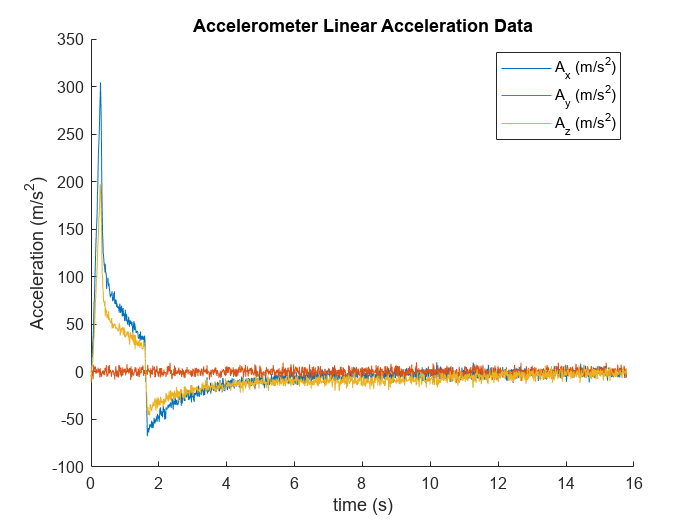

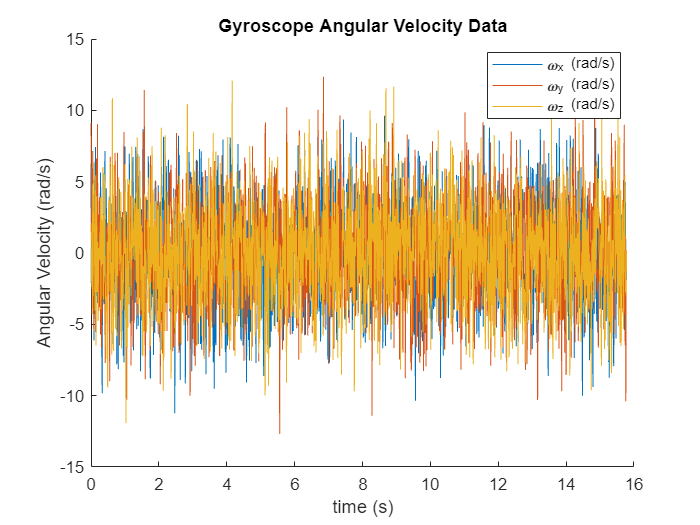

clc; clear; close all; format compact;
Create_IMU_noisy_data;

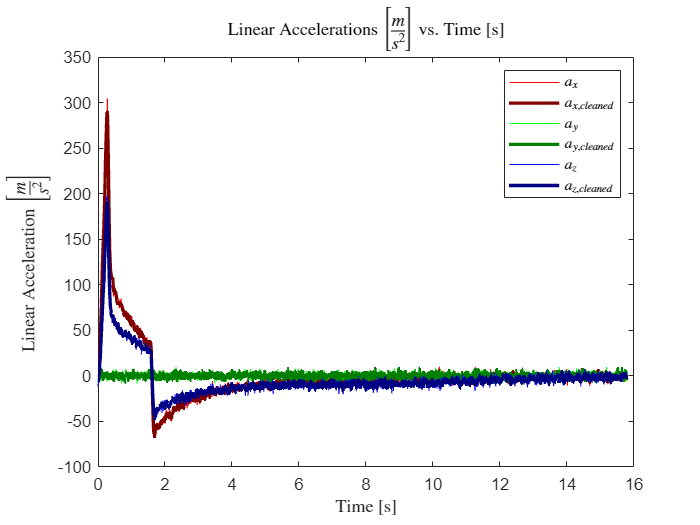

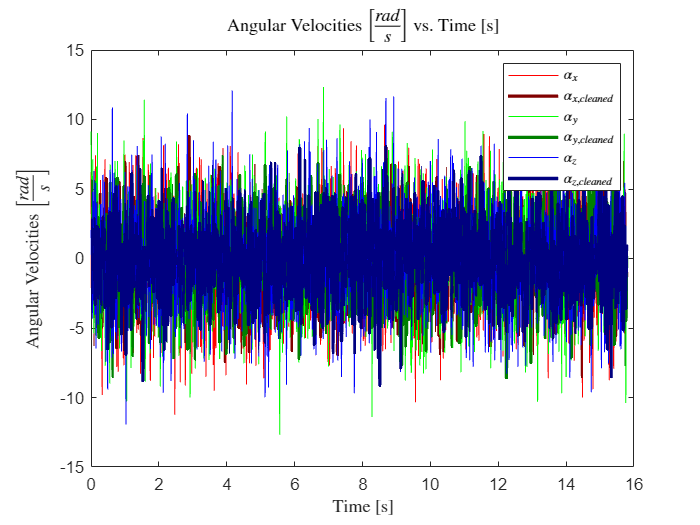

Data_Processing;

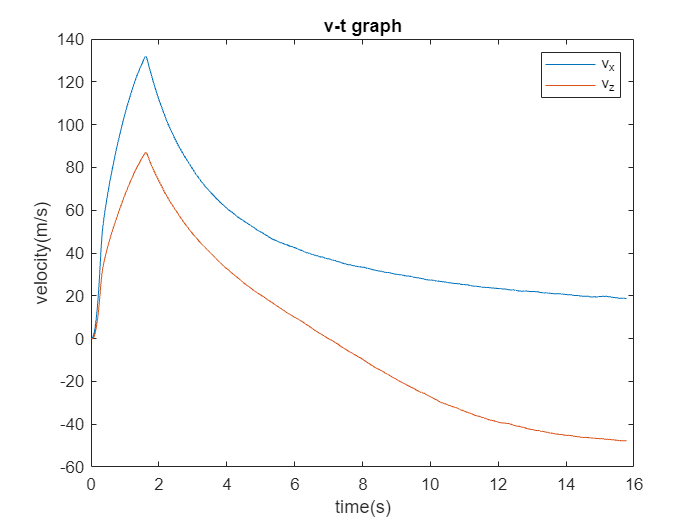

CleanedData = struct2array(load('Cleaned Acceleration Data'));

% time  ax  ay  az  omega_x  omega_y  omega_z


t = CleanedData(:,1); %s
a_x_i = CleanedData(:,2); %m/s^2
a_y_i= CleanedData(:,3);
a_z_i = CleanedData(:,4);
omega_x_b = CleanedData(:,5); %rad/s
omega_y_b = CleanedData(:,6); %rad/s
omega_z_b = CleanedData(:,7);

theta_y = cumtrapz(t,omega_y_b); %rad


v_x_i = cumtrapz(t,a_x_i);
v_z_i = cumtrapz(t,a_z_i);

x_i = cumtrapz(t,v_x_i);
z_i = cumtrapz(t,v_z_i);


figure
plot(t,v_x_i,t,v_z_i)
xlabel('time(s)');ylabel('velocity(m/s)');title('v-t graph')
legend('v_x','v_z')

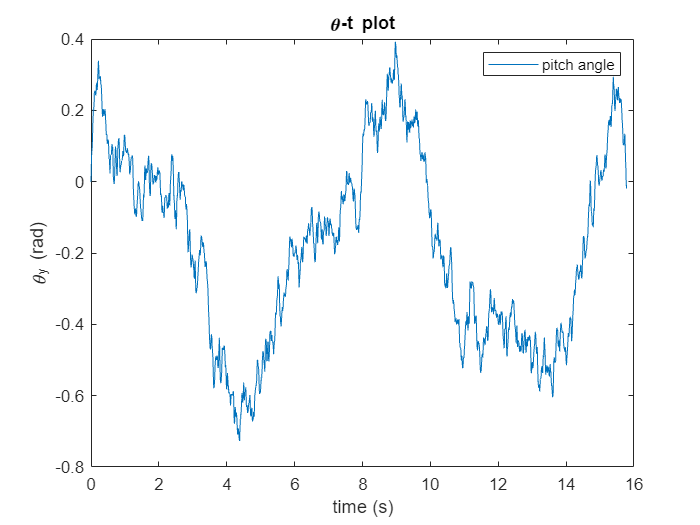

figure
plot(t,theta_y); xlabel('time (s)'); ylabel('\theta_y (rad)'); title('\theta-t plot')
legend('pitch angle')

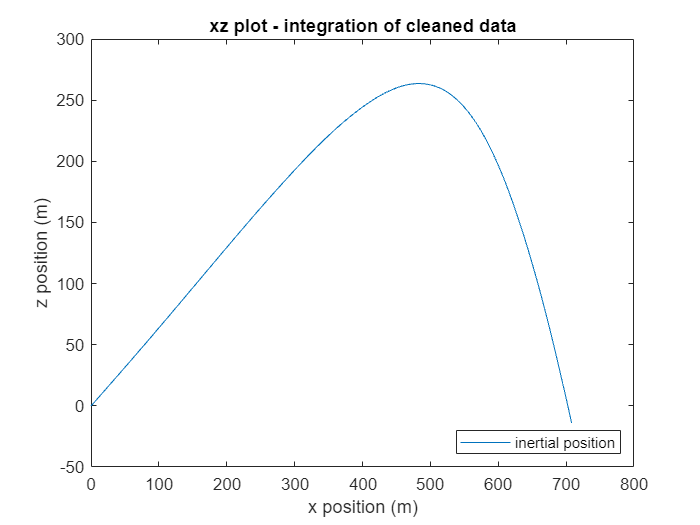

figure
plot(x_i,z_i); xlabel('x position (m)'); ylabel('z position (m)'); title('xz plot - integration of cleaned data') %x is negative for some reason
    legend('inertial position','location','southeast')